%% Convex Optimization using Steepest Descent (Gradient Descent) Method
%  Minimizes a convex function f(x) using the negative gradient direction.
%
%  Example objective: f(x1, x2) = (x1 - 3)^2 + (x2 - 2)^2 + x1*x2
%  Known minimum is near [x1, x2] = [2.67, 1.33] (approx)
%
%  Author : Generated Example
%  Method : Steepest Descent with fixed / backtracking line search

clear; clc; close all;

%% ── 1. Problem Definition ────────────────────────────────────────────────

% Objective function  f(x)
f = @(x) (x(1) - 3)^2 + (x(2) - 2)^2 + x(1)*x(2);

% Gradient of f(x)  ∇f(x)
grad_f = @(x) [2*(x(1) - 3) + x(2);   % ∂f/∂x1
               2*(x(2) - 2) + x(1)];   % ∂f/∂x2

%% ── 2. Algorithm Parameters ─────────────────────────────────────────────

x0          = [0; 0];      % Starting point
max_iter    = 1000;        % Maximum iterations
tol         = 1e-6;        % Convergence tolerance on gradient norm
alpha0      = 0.1;         % Initial step size (learning rate)

% Backtracking line-search parameters (Armijo condition)
use_backtracking = true;   % Set false to use fixed step size
beta             = 0.5;    % Step-size reduction factor  (0 < β < 1)
sigma            = 1e-4;   % Sufficient decrease constant (0 < σ < 0.5)

%% ── 3. Steepest Descent Iteration ───────────────────────────────────────

x        = x0;
history  = zeros(max_iter, 3);   % [x1, x2, f(x)] per iteration
converged = false;

fprintf('\n======================================================\n');

fprintf('  Steepest Descent Optimization\n');

  Steepest Descent Optimization


fprintf('======================================================\n');

fprintf('  Iter |   f(x)       |  ||grad||    |  Step α\n');

  Iter |   f(x)       |  ||grad||    |  Step α


fprintf('------------------------------------------------------\n');

------------------------------------------------------



for k = 1:max_iter

    g    = grad_f(x);          % Gradient at current point
    g_norm = norm(g);          % Euclidean norm of gradient
    fval   = f(x);

    history(k, :) = [x(1), x(2), fval];

    % ── Print progress every 50 iterations (and first 5) ─────────────
    if k <= 5 || mod(k, 50) == 0
        fprintf('  %4d | %12.6f | %12.6e | —\n', k, fval, g_norm);
    end

    % ── Convergence check ────────────────────────────────────────────
    if g_norm < tol
        fprintf('\n  ✓ Converged at iteration %d  (||grad|| = %.2e)\n', k, g_norm);
        history = history(1:k, :);
        converged = true;
        break
    end

    % ── Search direction: steepest descent = −∇f ─────────────────────
    d = -g;

    % ── Line search ───────────────────────────────────────────────────
    if use_backtracking
        alpha = alpha0;
        while f(x + alpha*d) > fval + sigma*alpha*(g'*d)
            alpha = beta * alpha;
        end
    else
        alpha = alpha0;   % Fixed step size
    end

    % ── Update ───────────────────────────────────────────────────────
    x = x + alpha * d;
end

     1 |    13.000000 | 7.211103e+00 | —
     2 |     8.560000 | 5.110773e+00 | —
     3 |     6.323600 | 3.649274e+00 | —
     4 |     5.178516 | 2.635400e+00 | —
     5 |     4.577534 | 1.934770e+00 | —
    50 |     3.666699 | 8.098376e-03 | —
   100 |     3.666667 | 4.173721e-05 | —



  ✓ Converged at iteration 136  (||grad|| = 9.40e-07)



if ~converged
    fprintf('\n  ✗ Did not converge within %d iterations.\n', max_iter);
    history = history(1:max_iter, :);
end

%% ── 4. Results ───────────────────────────────────────────────────────────

fprintf('\n======================================================\n');

fprintf('  Final Results\n');

  Final Results


fprintf('======================================================\n');

fprintf('  Optimal x1  = %.8f\n', x(1));

  Optimal x1  = 2.66666600


fprintf('  Optimal x2  = %.8f\n', x(2));

  Optimal x2  = 0.66666733


fprintf('  Optimal f*  = %.8f\n', f(x));

  Optimal f*  = 3.66666667


g_final = grad_f(x);
fprintf('  Gradient    = [%.2e, %.2e]\n', g_final(1), g_final(2));

  Gradient    = [-6.65e-07, 6.65e-07]


fprintf('======================================================\n\n');

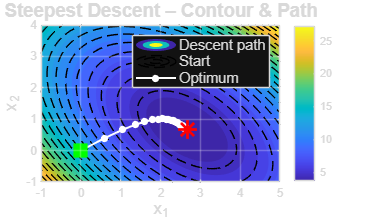


%% ── 5. Visualisation ─────────────────────────────────────────────────────

% 5a. Contour plot with descent path
figure('Name','Steepest Descent – Contour','NumberTitle','off','Color','w');

[X1, X2] = meshgrid(linspace(-1, 5, 300), linspace(-1, 4, 300));
F = (X1 - 3).^2 + (X2 - 2).^2 + X1.*X2;

contourf(X1, X2, F, 30, 'LineColor','none'); colormap(parula); colorbar;
hold on;
contour(X1, X2, F, 20, 'k', 'LineWidth', 0.5, 'LineStyle','--');

% Plot descent path
plot(history(:,1), history(:,2), 'w-o', ...
     'LineWidth', 1.5, 'MarkerSize', 4, 'MarkerFaceColor','w');
plot(x0(1), x0(2), 'gs', 'MarkerSize', 12, 'LineWidth', 2, ...
     'MarkerFaceColor','g', 'DisplayName','Start');
plot(x(1),  x(2),  'r*', 'MarkerSize', 14, 'LineWidth', 2, ...
     'DisplayName','Optimum');

xlabel('x_1','FontSize',13); ylabel('x_2','FontSize',13);
title('Steepest Descent – Contour & Path','FontSize',14,'FontWeight','bold');
legend({'Descent path','Start','Optimum'},'Location','northeast','FontSize',11);
grid on; hold off;

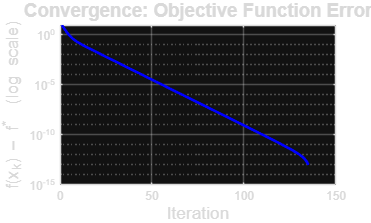


% 5b. Convergence plot – f(x) vs iteration
figure('Name','Convergence of f(x)','NumberTitle','off','Color','w');
semilogy(1:size(history,1), history(:,3) - f(x), 'b-', 'LineWidth', 2);
xlabel('Iteration','FontSize',13);
ylabel('f(x_k) – f^*  (log scale)','FontSize',13);
title('Convergence: Objective Function Error','FontSize',14,'FontWeight','bold');
grid on; box on;

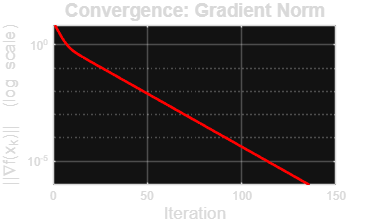


% 5c. Gradient norm vs iteration
grads = zeros(size(history,1), 1);
for i = 1:size(history,1)
    grads(i) = norm(grad_f(history(i,1:2)'));
end
figure('Name','Gradient Norm','NumberTitle','off','Color','w');
semilogy(1:length(grads), grads, 'r-', 'LineWidth', 2);
xlabel('Iteration','FontSize',13);
ylabel('||\nablaf(x_k)||  (log scale)','FontSize',13);
title('Convergence: Gradient Norm','FontSize',14,'FontWeight','bold');
grid on; box on;


%% ── Helper: verify with analytic solution ───────────────────────────────
% For f(x) = (x1-3)^2 + (x2-2)^2 + x1*x2
% Setting ∇f = 0:  2(x1-3)+x2 = 0  and  2(x2-2)+x1 = 0
% => 2x1 + x2 = 6  and  x1 + 2x2 = 4
% => x1 = 8/3 ≈ 2.6667,  x2 = 2/3 ≈ 0.6667
A_sys = [2, 1; 1, 2];
b_sys = [6; 4];
x_exact = A_sys \ b_sys;
fprintf('  Analytic optimum: x1 = %.8f,  x2 = %.8f\n', x_exact(1), x_exact(2));

  Analytic optimum: x1 = 2.66666667,  x2 = 0.66666667


fprintf('  Numeric  optimum: x1 = %.8f,  x2 = %.8f\n', x(1), x(2));

  Numeric  optimum: x1 = 2.66666600,  x2 = 0.66666733


fprintf('  Error: %.2e\n\n', norm(x - x_exact));

  Error: 9.40e-07

